## Kalman Filtering Example

clear all

% Set default text interpreter for plots
set(0, 'DefaultTextInterpreter', 'none')
set(0, 'DefaultLegendInterpreter', 'none')
set(0, 'DefaultAxesTickLabelInterpreter', 'none')

### Define a process model

% Sampling period
Ts = 0.5;

% Discrete-time transfer function
Gpd = tf(0.3, [1 -0.7], Ts);

### Generate some data by simulating the system 

% Number of sample periods
nT = 20;

% Time vector
t = Ts*(0:nT)';

% Input signal
u = zeros(nT+1,1);
u(t>=1) = 1;

[y, t] = lsim(Gpd,u,t);

% Add measurement noise
rng(0);
v = 0.5*randn(nT+1,1);
y_m = y + v;

### Plot simulation results

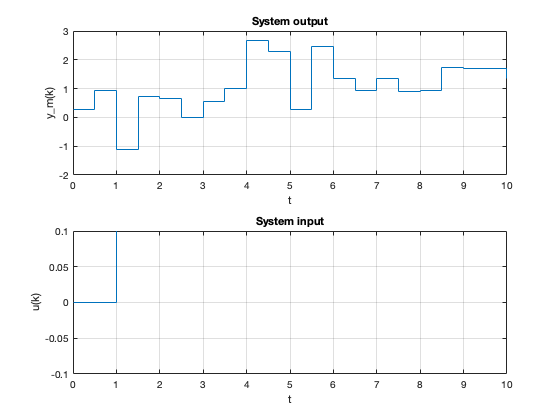

figure(1); clf
subplot(2,1,1)
stairs(t,y_m)
xlabel('t')
ylabel('y_m(k)')
title('System output')
grid on
subplot(2,1,2)
stairs(t,u)
ylim([-0.1 0.1])
xlabel('t')
ylabel('u(k)')
title('System input')
grid on

## Define observer

% Process model for use by observer
A = 0.7;
B = 1;
C = 0.3;
D = 0;

% Kalman filter parameters
P0 = 1000;  % initial variance of the estimate
Q = 0.01;  % estimated process noise variance
R = 0.5^2;  % measurement noise variance
KF1 = kalman_filter(A,B,C,D,Ts,P0,Q,R,'KF1');

### Simulate observer

% Array to store simulation results
y_est = nan(nT+1,1);
obs = KF1;
% Initial estimate (at t=0)
y_est(1,:) = obs.ykp1_est;
for i = 1:nT

    % update observer
    obs = update_KF(obs, u(i), y_m(i));
    
    % get estimate of output at next sample time
    y_est(i+1,:) = obs.ykp1_est;

end

### Compare observer estimates to plant data

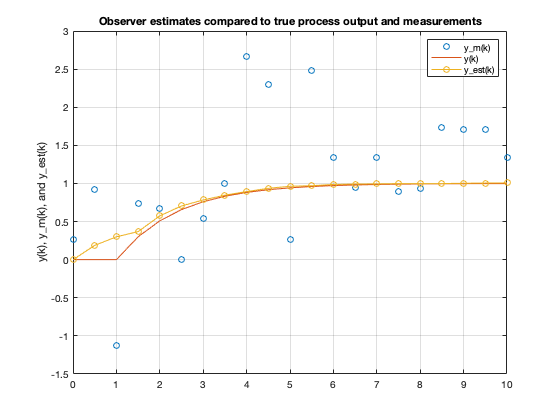

figure(2); clf
plot(t,y_m,'o',t,y,'-',t,y_est,'o-')
grid on
ylabel('y(k), y_m(k), and y_est(k)')
legend('y_m(k)','y(k)','y_est(k)')
title("Observer estimates compared to true process output and measurements")

% Display simulation results
table(t,u,y,v,y_m,y_est)

ans = 21×6 table
     t     u       y           v           y_m        y_est 
    ___    _    _______    _________    _________    _______

      0    0          0      0.26883      0.26883          0
    0.5    0          0      0.91694      0.91694    0.18766
      1    1          0      -1.1294      -1.1294    0.29976
    1.5    1        0.3      0.43109      0.73109    0.36797
      2    1       0.51      0.15938      0.66938    0.57489
    2.5    1      0.657     -0.65384    0.0031559    0.70478
      3    1     0.7599      -0.2168       0.5431    0.78321
    3.5    1    0.83193      0.17131       1.0032    0.84597
      4    1    0.88235       1.7892       2.6715     0.8933
    4.5    1    0.91765       1.3847       2.3024    0.93587
      5    1    0.94235     -0.67494      0.26